#### Set up

load('amsr_n3125_Arctic_m03_y2025-v5.4.mat');
addpath("E:\University\EngSci Thesis\Thesis work\external\m_map");

month = month_ts(1);
day = 12;
year = year_ts(1);

#### Parameters

%% seaice concentration of the day to be studied 2D matrix
seaice = double(squeeze(seaice_ts(day,:,:)));

%% Define the polynya region of interest (ROI),
lat_min = 70; 
lat_max = 70.5;
lon_min = -24;
lon_max = -21;

%% Linear array of indices of the matrix cells that represents a point in polynya
polynya_roi = find(lat>=lat_min & lat<=lat_max & lon >= lon_min & lon <= lon_max);

#### Stereographic Projection of Sea Ice Concentration data

figure('Color','w');
hold on;

% Set up polar stereographic projection
m_proj('stereographic', 'lat', 70.3, 'long', -22, 'rad', 1.5);

% Overlay sea ice concentration
m_pcolor(lon, lat, seaice);
colormap("turbo");
clim([0 100]);
colorbar;
title_string = sprintf('Stereographic Projection of Sea Ice Concentration (%u/%u/%u)', year, month, day);
title(title_string, 'FontSize', 13);

% Add coastlines
% m_coast;    % The most basic coastline resolution is used
m_grid;

hold off;

#### Showing Polynya ROI

figure('Color','w');
hold on;

% Set up polar stereographic projection
m_proj('stereographic', 'lat', 70.3, 'long', -22, 'rad', 1.5);


%%%% Optional: Underlay sea ice concentration
% m_pcolor(lon, lat, squeeze(seaice_ts(day,:,:)));
% colormap("turbo");
% clim([0 100]);
% colorbar;

%%%% Identify regions
for i = polynya_roi(:)'  % Loop through each point in polynya
    if ~isnan(seaice(i))        % plot the point, if it does not correspond to land
        m_plot(lon(i), lat(i), '+', 'Color', 'k');
    end
end
title('Defined Region of Interest', 'FontSize', 13);

% Add coastlines
m_coast;    % The most basic coastline resolution is used
m_grid;

hold off;

#### Calculating Area of Open Water

Area of open water per cell (AOW_i) = (100 - ice_concentration)/100 × 3.125 km²

addpath("E:\University\EngSci Thesis\Thesis work\functions");

aow = calcOpenWater(seaice, lat, lon, [70, 70.5], [-24, -21])

  371.4767



    0.1630

    0.0765

    0.0184

    0.0983

    0.0649

    0.0889

    0.0443

    0.0595

    0.0724

    0.1545

    0.1527

    0.1627

    0.0859

    0.1227

    0.1776

    0.0882

    0.1018

    0.0805

    0.1319

    0.2642

    0.1396

    0.1299

    0.2110

    0.1163

    0.1313

    0.1655

    0.1083

    0.0621

    0.0673

    0.3231

    0.3518

    0.2811

    0.1625

    0.2143

    0.2289

    0.0776

    0.0608

    0.0701

    0.0590

    0.0590

    0.3324

    0.3931

    0.3458

    0.2063

    0.2227

    0.1654

    0.1572

    0.0448

    0.0502

    0.0652

    0.3223

    0.3657

    0.3361

    0.2287

    0.2551

    0.2024

    0.1843

    0.0206

    0.0427

    0.3306

    0.4287

    0.3945

    0.2588

    0.1596

    0.1659

    0.0652

    0.0438

    0.2679

    0.4327

    0.4442

    0.2509

    0.2208

    0.0997

    0.0442

    0.0359

    0.3343

    0.4438

    0.4502

    0.2705

    0.2356

    0.2109

    0.0327

    0.0328

    

areas =    87.7467   13.6944   27.1159    7.0394   38.2291  158.5253  156.4101  105.5134   69.2711  212.9891  291.6386  371.4767  295.6183  424.7763   86.2563  174.1183  156.2818  199.2331  292.5788   91.0787  139.8727   97.5377  119.6268  144.8466  112.4746  198.4328  194.1288  194.8606  190.8078  182.0324


#### Time series of daily polynya size

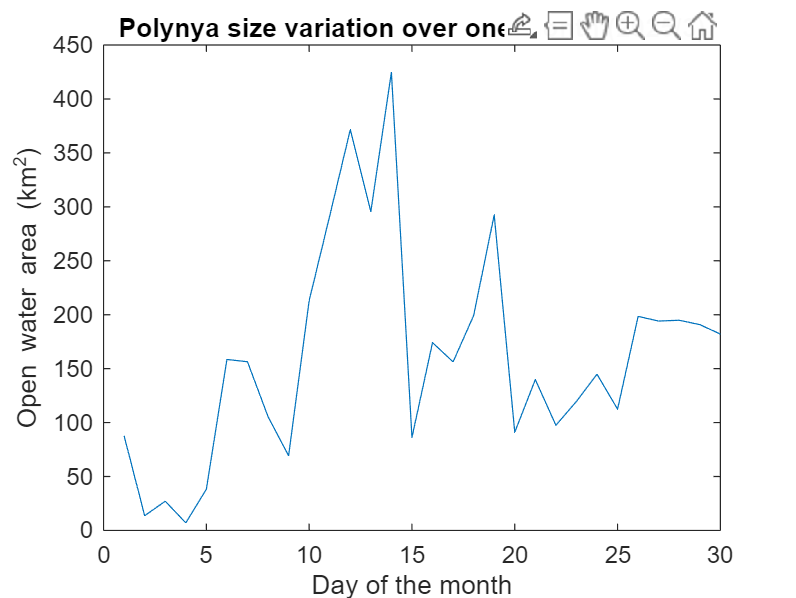

areas = daily_area(seaice_ts, lat,lon, [70, 70.5], [-24, -21])

% Plot time series of open water area over one month
plot(day_ts(1:30), areas)
title_string = sprintf('Polynya size variation over one month (%u/%u)', year, month);
title(title_string)
xlabel('Day of the month')
ylabel('Open water area (km^2)')